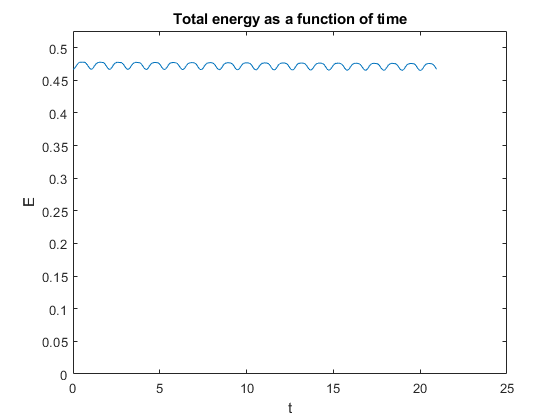

clc
clear all
g=9.81;
R=g/9;
thetad0=0;
theta0=0.3;
[t,w]=pendulum2(R,theta0,thetad0);
K=0.5*R^2*w(:,2).^2;
V=0.5*9*R^2*(sin(w(:,1))).^2;
E=K+V;
plot(t,E)
axis([0 25 0 max(E)*1.1])
xlabel('t')
ylabel('E')
title('Total energy as a function of time')

(a) The variation of total energy is relativly small 

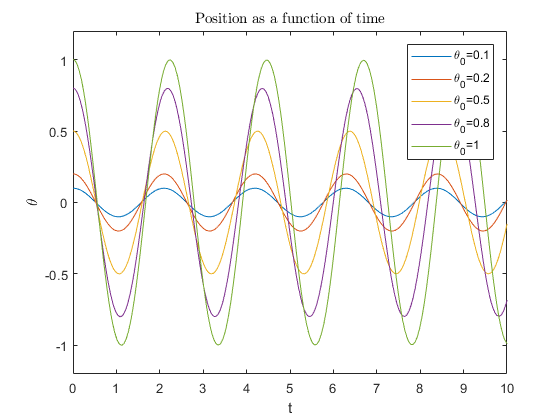

for theta0=[0.1 0.2 0.5 0.8 1]
[t,w]=pendulum2(R,theta0,thetad0);
plot(t,w(:,1))
xlabel('t')
ylabel('\theta')
title('Position as a function of time','interpreter','latex')
axis([0 10 -1.2 1.2])
hold on
end
legend('\theta_{0}=0.1','\theta_{0}=0.2','\theta_{0}=0.5','\theta_{0}=0.8','\theta_{0}=1')
hold off

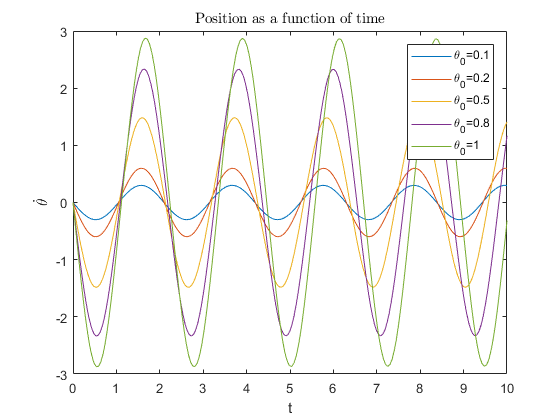

for theta0=[0.1 0.2 0.5 0.8 1]
[t,w]=pendulum2(R,theta0,thetad0);
plot(t,w(:,2))
xlabel('t')
ylabel('$\dot{\theta}$','interpreter','latex')
title('Position as a function of time','interpreter','latex')
axis([0 10 -3 3])
hold on
end
legend('\theta_{0}=0.1','\theta_{0}=0.2','\theta_{0}=0.5','\theta_{0}=0.8','\theta_{0}=1')
hold off

(b) we can see from these two graphs that not only the amplitude will change, but also the period will change. As initial angle increase, the amplitude will increase and the period will increase as well. However, in the linear case , the period will be independent of the amplitude. The period would be longer in nonlinear case.

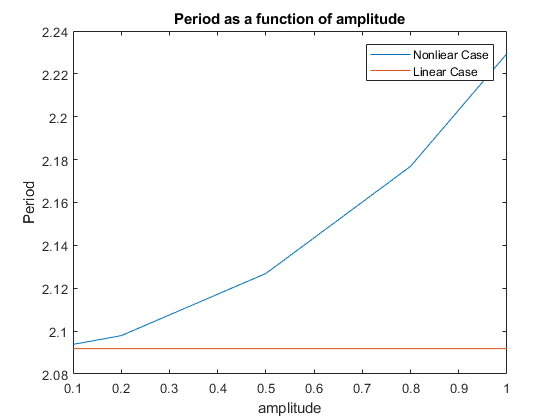

i=0;
for theta0=[0.1 0.2 0.5 0.8 1]
i=i+1;
[t1,w1]=pendulum2(R,theta0,thetad0);
[t2,w2]=pendulum(R,theta0,thetad0);
thetam1(i)=max(w1(:,1));
ind1= find(w1(:,2).*circshift(w1(:,2), [-1 0]) <= 0);
period1(i)= 2*mean(diff(t1(ind1(1:end-1))));
ind1=zeros;
thetam2(i)=max(w2(:,1));
ind2= find(w2(:,2).*circshift(w2(:,2), [-1 0]) <= 0);
period2(i)= 2*mean(diff(t2(ind2(1:end-1))));
ind2=zeros;
end
plot(thetam1,period1,thetam2,period2)
xlabel('amplitude')
ylabel('Period')
title('Period as a function of amplitude')
legend('Nonliear Case','Linear Case')